%%The code models the distribution of temperature over a rod of length L
%%by solving a linear system of equations through a function implemented
%%after the section break of this file.
clear
L = 10;
n = 5;
h = 0.05;
T_I = 200;
t0 = 300;
tn = 400;
dx = L/n;
dsq = 1/(dx^2);
c1 = -h*T_I - t0*dsq;
c2 = -h*T_I - tn*dsq;
c3 = -h*T_I;
A = [(-h-2*dsq) , dsq , 0 , 0 ; dsq , (-h-2*dsq) , dsq , 0 ; 0 , dsq , (-h-2*dsq) , dsq ; 0 , 0 , dsq , (-h-2*dsq)];
R = [ c1 ; c3 ; c3 ; c2];
sx = A\R

sx =   283.2660
  283.1853
  299.7416
  336.2462


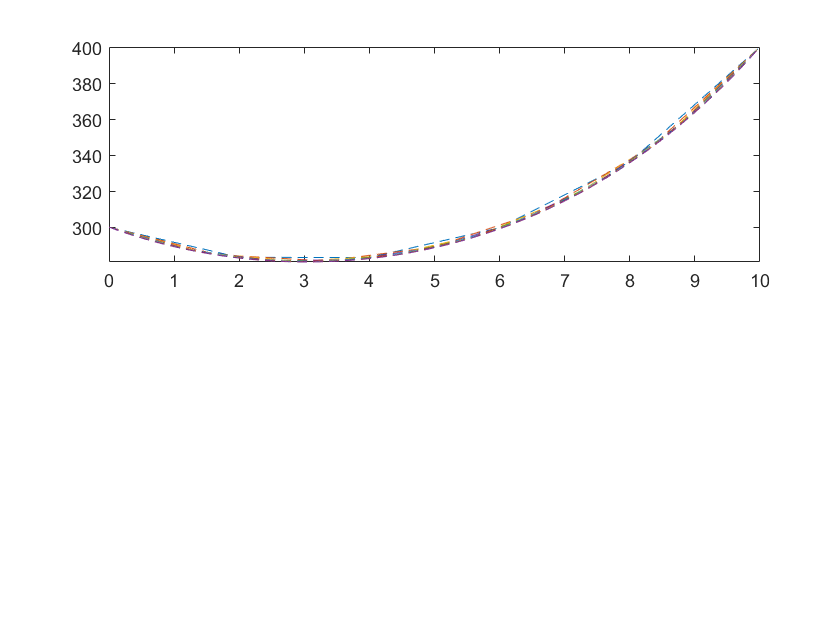

subplot(2,1,1)
for i = 5:50
N = i;
x = 0:N;
x(1) = t0;
x(end) = tn;
ti = 0:10/N:10;
t = ti(2:end-1);
[ssx] = z_leb(L,T_I,t0,tn,N,h);
x(2 : end-1) = ssx;
plot(ti,x,'--')
hold on
end

function [x] = z_leb(L,T_I,t0,tn,n,h)
dx = L/n;
dsq = 1/(dx^2);
c1 = -h*T_I - t0*dsq;
c2 = -h*T_I - tn*dsq;
c3 = -h*T_I;
c4 = -h-2*dsq;

Ri = NaN(1,n-1);
Ri(1,1) = c1;
Ri(1,end) = c2;
Ri(2:end-1) = c3;
R = Ri';
v = NaN(1,n-1);
v(1:end) = c4;
l1 = NaN(1,n-2);
l1(1:end) = dsq;
l2 = NaN(1,n-2);
l2(1:end) = dsq;
M1 = diag(v);
M2 = diag(l1,1);
M3 = diag(l2,-1);
M = M1 + M2 + M3;

x = M\R;
end